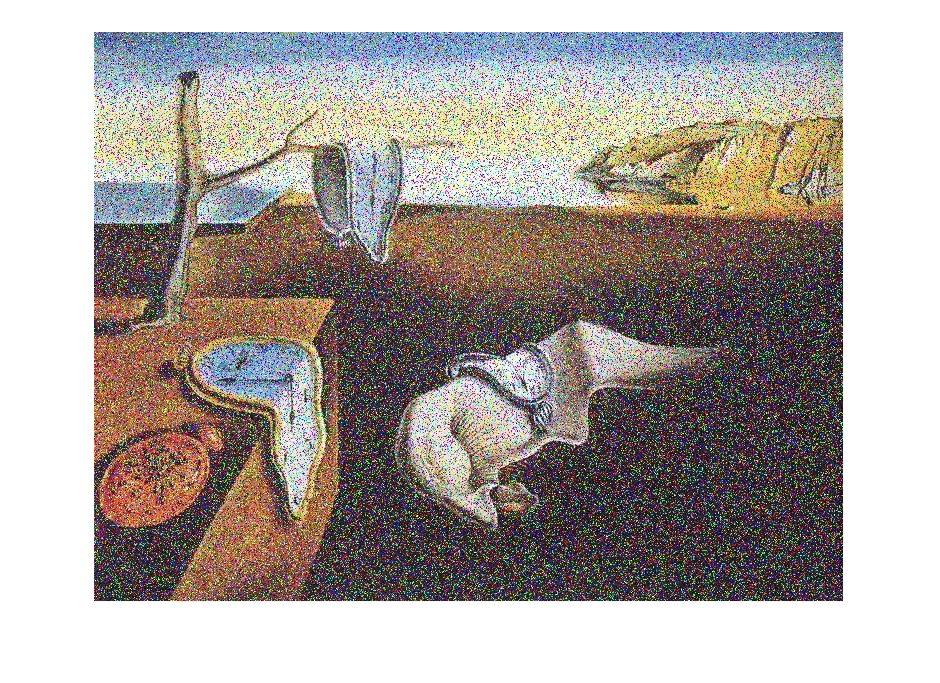

clc;
clear all;
close all;

% Load the original color image and grayscale puzzle pieces
originalImage = imread('noisy_colorful_image.jpg'); % replace with the actual filename of the original image
imshow(originalImage);

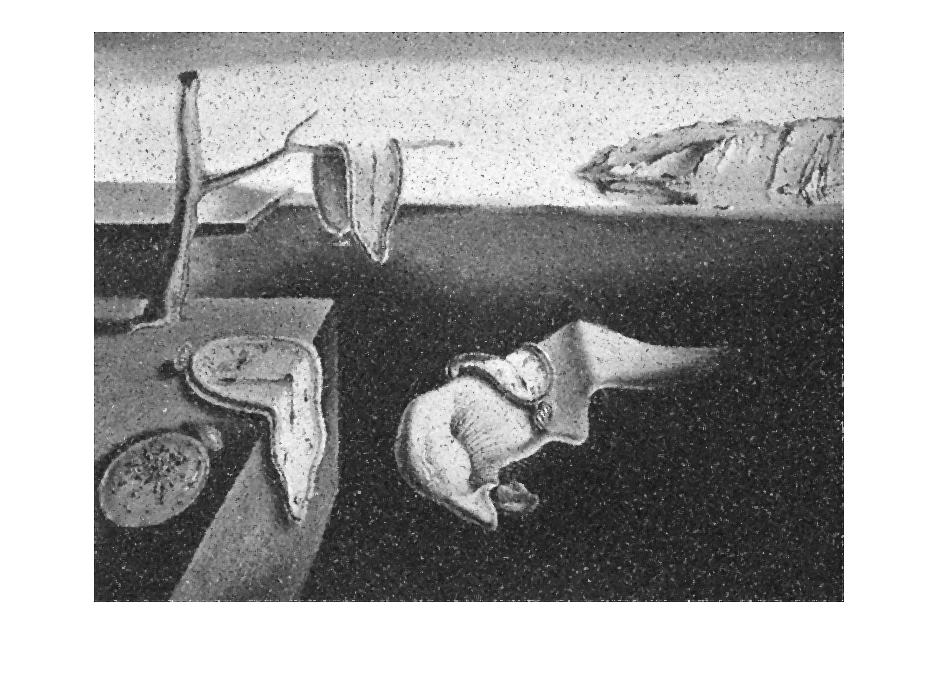

denoisedImage = medfilt2(rgb2gray(originalImage), [3 3]);
imshow(denoisedImage)

`medfilt2``(`[`I`](https://localhost:31515/static/help/images/ref/medfilt2.html?searchHighlight=medfilt2&searchResultIndex=1#bupa05x-1-A)`)` performs median filtering of the image `I` in two dimensions. Each output pixel contains the median value in a 3-by-3 neighborhood around the corresponding pixel in the input image.

% Cropping image pieces to reduce the white borders
for k=1:16
i = imread(sprintf('piece%d.jpg', k));
gImg = rgb2gray(i);
th = 210; 
mask = gImg < th;
[row, col] = find(mask);
trow = min(row);
brow = max(row);
lcol = min(col);
rcol = max(col);
cropped = i(trow:brow, lcol:rcol, :);

imwrite(cropped, sprintf('new_piece%d.jpg', k));
end

**Thresholding to Create a Binary Mask**

- Create binary mask to separate content from whitespace

- th = 210: A threshold is set to 225 (close to white, since white in grayscale is 255).

**Determine Bounding Box:**

- mask = gImg < th: Creates a binary mask where pixels less than 225 (darker than near-white) are considered part of the actual image, while white areas (≥ 225) are ignored.

- find(mask) returns the row (row) and column (col) indices where the mask is true, i.e., where pixels are not white.

**Crop Image:**

- Extract the region of interest using crop

puzzleFolder = 'puzzleimages'; % folder containing the 16 puzzle pieces
numPieces = 16;
gridSize = 4; % 4x4 grid

% Convert the original image to grayscale
grayOriginal = denoisedImage;

% Get the dimensions of the original grayscale image
[rows, cols] = size(grayOriginal);

% Calculate integer dimensions for each block
blockRows = floor(rows / gridSize);
blockCols = floor(cols / gridSize);

% Initialize a cell array to store 4x4 blocks of the original image
originalBlocks = cell(gridSize, gridSize);

% Split the original image into 4x4 blocks
for i = 1:gridSize
    for j = 1:gridSize
        % Calculate the row and column ranges for each block
        rowRange = (i-1)*blockRows + 1 : min(i*blockRows, rows); % Ensure we stay within bounds
        colRange = (j-1)*blockCols + 1 : min(j*blockCols, cols); % Ensure we stay within bounds
        
        % Extract the block and store it in the cell array
        originalBlocks{i, j} = grayOriginal(rowRange, colRange);
    end
end

% Load each puzzle piece and store it in an array
puzzlePieces = cell(numPieces, 1);
for k = 1:numPieces
    pieceFilename = fullfile(puzzleFolder, sprintf('new_piece%d.jpg', k)); % replace with the actual filenames of the pieces
    puzzlePieces{k} = imread(pieceFilename);
end

% Initialize a matrix to store the final arrangement of puzzle pieces
finalArrangement = zeros(gridSize, gridSize);

% Initialize an array to keep track of used puzzle pieces
usedPieces = false(numPieces, 1); % false means the piece hasn't been used yet

% Loop through each block of the original image and find the best matching puzzle piece
for i = 1:gridSize
    for j = 1:gridSize
        bestMatch = inf;
        bestPiece = 0;
        
        % Compare each unused puzzle piece to the current block
        for k = 1:numPieces
            if ~usedPieces(k)  % Only consider pieces that haven’t been used
                piece = puzzlePieces{k};
                resizedPiece = imresize(piece, [blockRows, blockCols]); % Resize to match the block size
                
                % Convert the puzzle piece to grayscale if it is RGB
                if size(resizedPiece, 3) == 3
                    resizedPiece = rgb2gray(resizedPiece);
                end
                
                % Calculate the similarity measure
                diff = sum((double(originalBlocks{i, j}) - double(resizedPiece)).^2, 'all');
                
                if diff < bestMatch
                    bestMatch = diff;
                    bestPiece = k;
                end
            end
        end
        
        % Assign the best matching piece to the current position
        finalArrangement(i, j) = bestPiece;
        usedPieces(bestPiece) = true; % Mark this piece as used
    end
end

% Display the final arrangement as a 4x4 matrix of piece numbers
disp('Final arrangement of puzzle pieces (as matrix):');

Final arrangement of puzzle pieces (as matrix):


disp(finalArrangement);

     6     9     4    11
    14    16    15    13
     5     2     1     3
    12     8    10     7



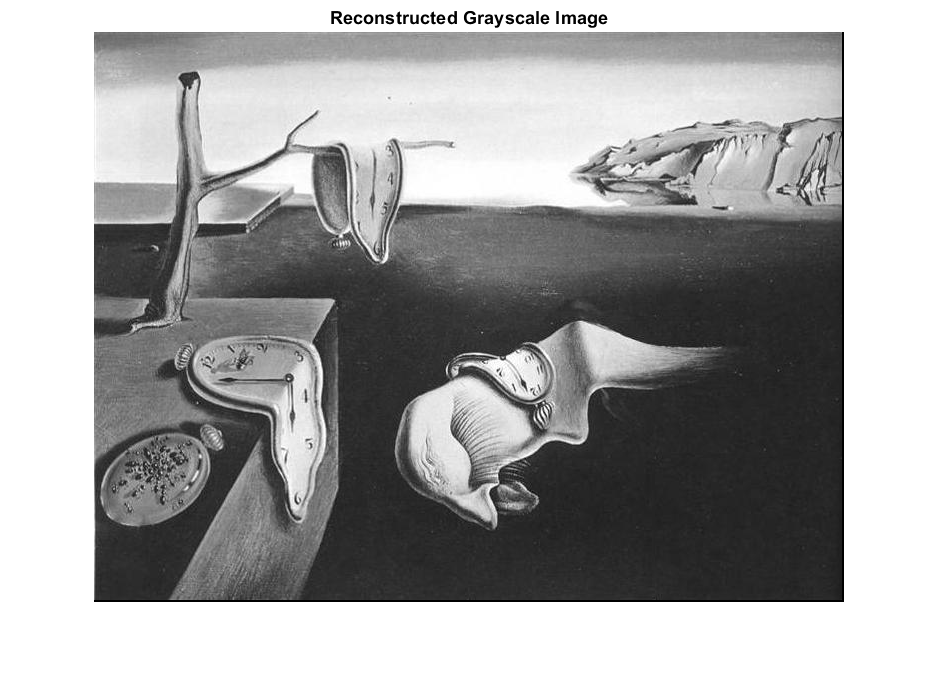


% Initialize the reconstructed image as grayscale
reconstructedImage = uint8(zeros(rows, cols));

for i = 1:gridSize
    for j = 1:gridSize
        % Define the range for each block in the reconstructed image
        rowRange = (i-1)*blockRows + 1 : i*blockRows;
        colRange = (j-1)*blockCols + 1 : j*blockCols;
        
        % Resize the puzzle piece to the required dimensions
        piece = imresize(puzzlePieces{finalArrangement(i, j)}, [blockRows, blockCols]);
        
        % Convert the puzzle piece to grayscale if it is RGB
        if size(piece, 3) == 3
            piece = rgb2gray(piece);
        end
        
        % Assign the grayscale piece to the appropriate location in the reconstructed image
        reconstructedImage(rowRange, colRange) = piece;
    end
end

% Display the reconstructed grayscale image
figure;
imshow(reconstructedImage);
title('Reconstructed Grayscale Image');